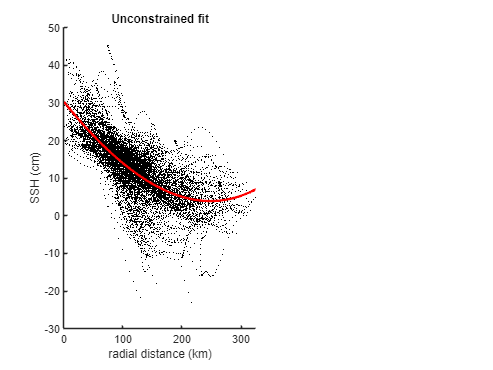

% % Define the eddy
% A = 0.10; % amplitude in m
% L = 80e3; % length in m
% eddy = @(r) A*exp(-r.*r/L/L);
% 
% % Create some noise
sigma = 10;%0.01;
noiseDistribution = StudentTDistribution(sigma,3.0);
% noiseDistribution = NormalDistribution(sigma);
% 
% % Now create some observations of the eddy with noise
% % rng(1)
% r = linspace(0,4*L,100).';
% ssh = eddy(r) + noiseDistribution.rand(size(r));
% xEt, yEt, ssht are arrays
r=sqrt(xEt(~isnan(ssht)).^2+yEt(~isnan(ssht)).^2);
ssht=ssht(~isnan(ssht));
L=max(r);

% create a spline basis
% M indicates how many splines to create
K = 4; % *order* of the spline (K=4 is a cubic spline)
tKnot = BSpline.knotPointsForDataPoints(sort(r),K=K,M=4);

% Do a simple least-squares fit to the data with these splines
constraints = struct('t',[],'D',[]);
spline = ConstrainedSpline(r,ssht,K,tKnot,noiseDistribution,constraints);
% spline = ConstrainedSpline(r,ssht,K,tKnot,constraints);
tq = linspace(0,4*L,1000).';

figure
tl = tiledlayout(1,2,TileSpacing="tight");
nexttile

% plot(tq/1e3,eddy(tq),Color=[0 0 0],LineWidth=1.0)
scatter(r,ssht,1,'k', 'filled'), hold on
plot(tq,spline(tq),Color='r',LineWidth=2)
xlabel('radial distance (km)')
ylabel('SSH (cm)')
title('Unconstrained fit')
xlim([0 max(r)])

% ylim([-3*sigma eddy(0)+3*sigma])


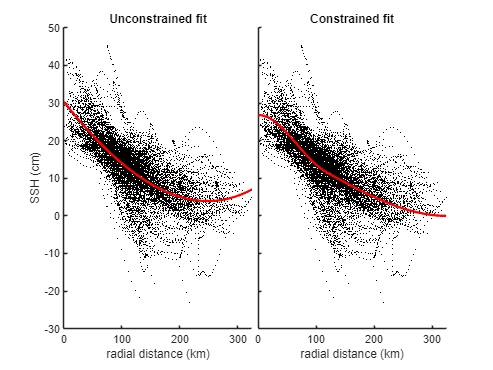

% The constraints let you set the value of the spline, or a derivative, to
% zero. So this example forces the fit to be zero at r_max, and the first
% derivative to be zero at r=0. We add two more splines, because we are
% adding two constraints.
tKnot = BSpline.knotPointsForDataPoints(sort(r),K=K,M=6);
constraints = struct('t',[min(r); max(r); max(r)],'D',[1;0;1]);
spline_constrained = ConstrainedSpline(r,ssht,K,tKnot,noiseDistribution,constraints);

nexttile
% plot(tq/1e3,eddy(tq),Color=[0 0 0],LineWidth=1.0), hold on
scatter(r,ssht,1,'k', 'filled'), hold on
plot(tq,spline_constrained(tq),Color='r',LineWidth=2)
set(gca,'YTickLabel',[]);
xlabel('radial distance (km)')
title('Constrained fit')
xlim([0 max(r)])

% ylim([-3*sigma eddy(0)+3*sigma])

Xn = BSpline.Spline( t_spline, tKnot, K, 0 );

Unrecognized function or variable 't_spline'.

xi = Xn\x_spline;%how should I allow nan
B = BSpline.Spline( tq, tKnot, K, 1 );
Vq = squeeze(B(:,:,2));
figure, plot(tq,Vq*xi)
xlabel('Radial distance (km)'),ylabel('d\eta/dr \times 10^{-5}')